## Problem 7: Numeric Differentiation and Integration

1) Calculating acceleration and displacement from velocity

v = [0, 6, 8, 2, 2, 4, -2];
t = [0, 20, 40, 50, 70, 90, 100];

Acceleration

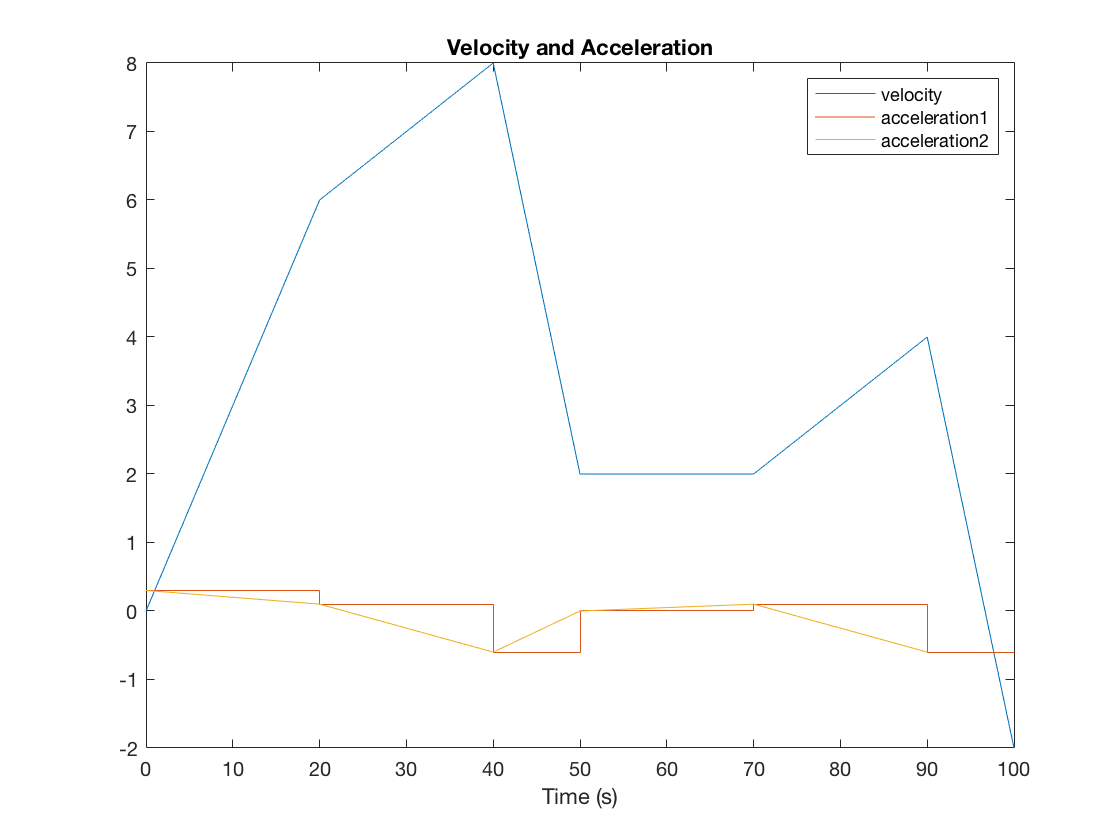

%homegrown function
dv =  diff(v);
dt = diff(t);
a = dv./dt;
a = [a, a(1, end)];

plot(t, v,'DisplayName', 'velocity')
hold on
stairs(t, a,'DisplayName', 'acceleration1')
legend
title("Velocity and Acceleration")
xlabel("Time (s)")

%built-in function
a = diff(v)./diff(t);
plot(t(1:length(a)), a, 'DisplayName', 'acceleration2')
hold off

Displacement

%homegrown function
h = diff(t);
for i = 1:length(v)-1
    trap(i) = 0.5*(v(i)+v(i+1))*h(i);
end
d = sum(trap);
fprintf('Integral calculated using homegrown function = %d', d)

Integral calculated using homegrown function = 360

For this function it makes more sense to use the trapezoid method than Simpson's method to calculate the integral because the trapezoid method can exactly integrate a linear function like this one

%built-in function
d = trapz(t, v);
fprintf('Integral calculated using built-in function = %d', d)

Integral calculated using built-in function = 360

2 )$f\left(x\right)={\mathrm{sin}}^2 \left(\frac{1}{x\left(2-x\right)}\right)$

a) $\frac{d}{\mathit{dx}}\left(\sin^2 \left(\frac{1}{x\left(2-x\right)}\right)\right)$

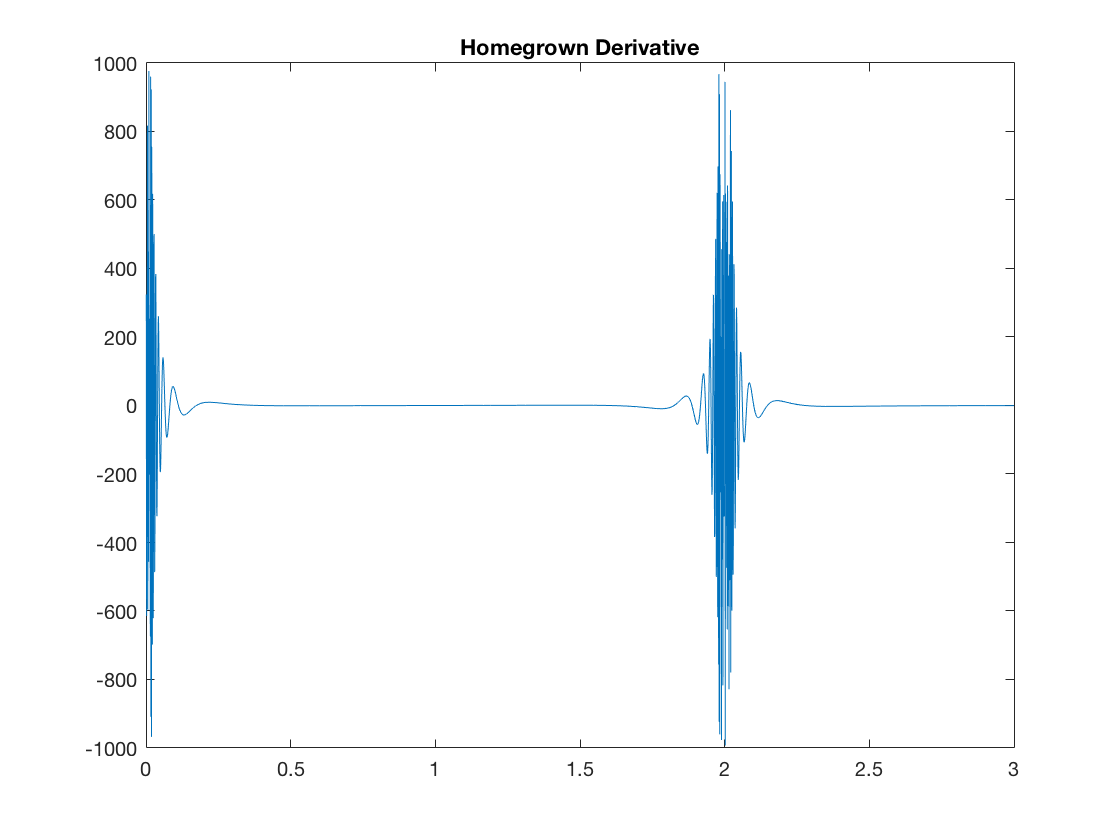

F = @(x) (sin(1./(x.*(2-x)))).^2;
h = 0.001;
j = 0:h:3;

%homegrown derivative
n = 1;
for i = 0:h:3
    dF(n) = (F(i+h)-F(i))/h;
    n = n + 1;
end

plot(j, dF)
title("Homegrown Derivative")
axis([0, 3, -1000, 1000])

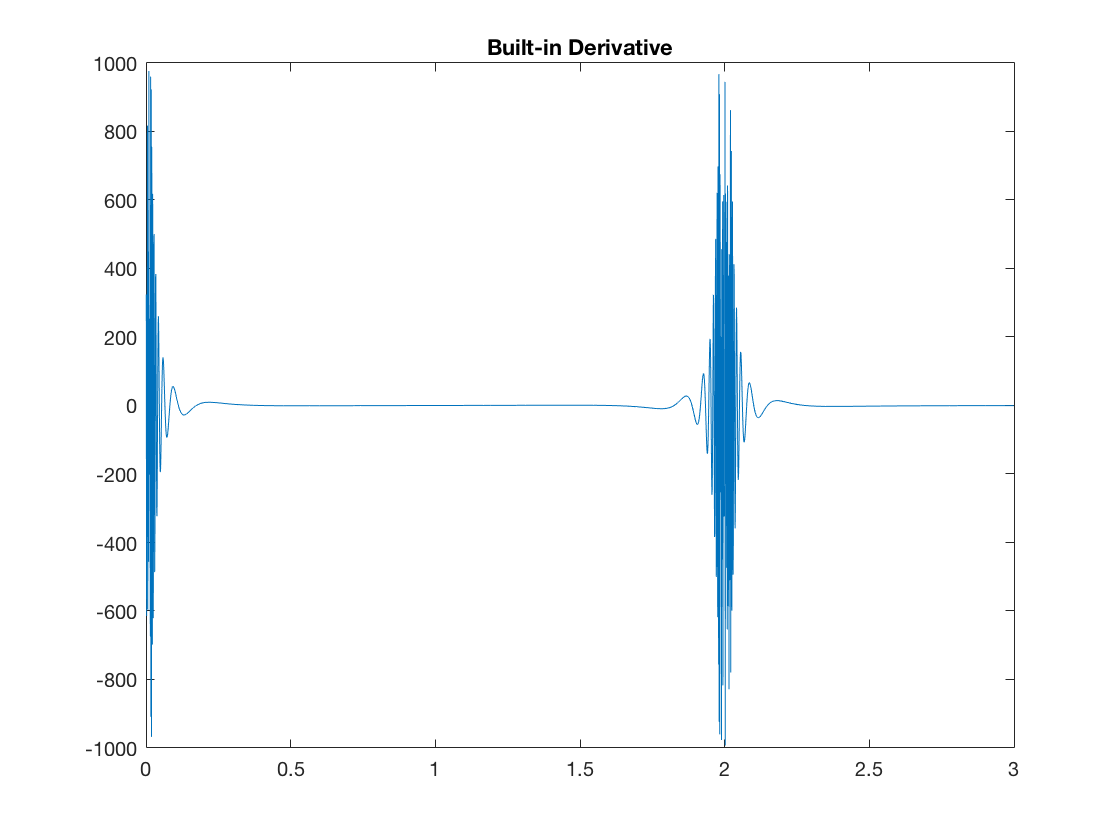

%built-in derivative
f = F(0:h:3);
t = 0:h:3;

d = diff(f)./diff(t);
plot(t(1:(end-1)), d, '-')
title("Built-in Derivative")
axis([0, 3, -1000, 1000])

This function hits problems at x = 0 and x = 2 because the function is discontinuous at those points. This causes the graphs of the derivatives to oscillate betwen very large positive and negative numbers at those points.

b) $\int_0^2 \sin^2 \left(\frac{1}{x\left(2-x\right)}\right)\mathit{dx}$

F = @(x) (sin(1./(x.*(2-x)))).^2;

%homegrown integral: trapezoid rule
h = 0.0001;
I = trapezoidI(F, 0+h, 2-2*h, h); %adjusting the bounds by h avoids the points of discontinuity
error = trapezoidIerror(F, 0+h, 2-2*h, h);
fprintf('Integral calculated using trapezoid rule = %f %c %f', I, char(177), error)

Integral calculated using trapezoid rule = 1.450989 ± 0.000120

%homegrown integral: simpson rule
I = simpsonI(F, 0+h, 2-2*h, h);
error = simpsonIerror(F, 0+h, 2-2*h, h);
fprintf('Integral calculated using simpson rule = %f %c %f', I, char(177), error)

Integral calculated using simpson rule = 1.450904 ± 0.000017

%built-in integral
I = integral(F, 0, 2);

fprintf('Integral calculated using built-in function = %f %c %d', I, char(177), 3.5e-6)

Integral calculated using built-in function = 1.451401 ± 3.500000e-06

%Romberg method
[I, accuracy] = rombergI(F, 0+h, 2-2*h, 1e-12);
fprintf('Integral calculated using romberg method = %f %c %d', I, char(177), accuracy)

Integral calculated using romberg method = 1.451352 ± 1.000000e-12

3) Calculating Integrals


$$\int_0^{\pi } \mathrm{sin}\left(x^2 \right)\mathrm{dx}$$


F = @(x) sin(x.^2);

%homegrown function: trapezoid rule
h = 0.0001;
I = trapezoidI(F, 0, pi, h);
error = trapezoidIerror(F, 0, pi, h);
fprintf('Integral calculated using trapezoid rule = %f %c %f', I, char(177), error)

Integral calculated using trapezoid rule = 0.772627 ± 0.000007

%homegrown function: simpson rule
I = simpsonI(F, 0, pi, h);
error = simpsonIerror(F, 0, pi, h);
fprintf('Integral calculated using simpson rule = %f %c %f', I, char(177), error)

Integral calculated using simpson rule = 0.772606 ± 0.000003

%built-in function
I = integral(F, 0, pi);
fprintf('Integral calculated using built-in function = %f %c %d', I, char(177), 1e-10)

Integral calculated using built-in function = 0.772652 ± 1.000000e-10

%romberg method
[I, accuracy] = rombergI(F, 0, pi, 1e-12);
fprintf('Integral calculated using romberg method = %f %c %d', I, char(177), accuracy)

Integral calculated using romberg method = 0.772637 ± 1.000000e-12


$$\int_0^{\pi } {\mathrm{sin}}^2 \left(x^2 \right)\mathrm{dx}$$


F = @(x) (sin(x.^2)).^2;

%homegrown function: trapezoid rule
h = 0.0001;
I = trapezoidI(F, 0, pi, h);
error = trapezoidIerror(F, 0, pi, h);
fprintf('Integral calculated using trapezoid rule = %f %c %f', I, char(177), error)

Integral calculated using trapezoid rule = 1.319027 ± 0.000003

%homegrown integral: simpson rule
I = simpsonI(F, 0, pi, h);
error = simpsonIerror(F, 0, pi, h);
fprintf('Integral calculated using simpson rule = %f %c %f', I, char(177), error)

Integral calculated using simpson rule = 1.319036 ± 0.000001

%built-in function
I = integral(F, 0, pi);
fprintf('Integral calculated using built-in function = %f %c %d', I, char(177), 1e-10)

Integral calculated using built-in function = 1.319017 ± 1.000000e-10

%romberg method
[I, accuracy] = rombergI(F, 0, pi, 1e-12);
fprintf('Integral calculated using romberg method = %f %c %d', I, char(177), accuracy)

Integral calculated using romberg method = 1.319023 ± 1.000000e-12


$$\int_1^{e^{\pi /2} } \cos \left(\mathrm{ln}\left(x\right)\right)\textrm{dx}$$


F = @(x) cos(log(x));

%homegrown function: trapezoid rule
h = 0.0001;
I = trapezoidI(F, 1, exp(pi/2), h);
error = trapezoidIerror(F, 1, exp(pi/2), h);
fprintf('Integral calculated using trapezoid rule = %f %c %f', I, char(177), error)

Integral calculated using trapezoid rule = 1.905189 ± 0.000017

%homegrown integral: simpson rule
I = simpsonI(F, 1, exp(pi/2), h);
error = simpsonIerror(F, 1, exp(pi/2), h);
fprintf('Integral calculated using simpson rule = %f %c %f', I, char(177), error)

Integral calculated using simpson rule = 1.905205 ± 0.000002

%built-in function
I = integral(F, 1, exp(pi/2));
fprintf('Integral calculated using built-in function = %f %c %d', I, char(177), 1e-10)

Integral calculated using built-in function = 1.905239 ± 1.000000e-10

%romberg method
[I, accuracy] = rombergI(F, 1, exp(pi/2), 1e-12);
fprintf('Integral calculated using romberg method = %f %c %d', I, char(177), accuracy)

Integral calculated using romberg method = 1.905226 ± 1.000000e-12

 
$$\int_1^{2\pi } \frac{\mathrm{sin}\left(x\right)}{\mathrm{ln}\left(x\right)}\textrm{dx}$$


F = @(x) sin(x)./log(x);

%homegrown function
h = 0.0001;
I = trapezoidI(F, 1, 2*pi, h);
error = trapezoidIerror(F, 1, 2*pi, h);
%This function is divergent, so the error of the calculated integral does not
%decrease as the step size is decreased
fprintf('Integral calculated using trapezoid rule = %f %c %f', I, char(177), error)

Integral calculated using trapezoid rule = 8.364053 ± 0.194437

%built-in function
I = integral(F, 1, 2*pi);

fprintf('Integral calculated using built-in function = %f', I)

Integral calculated using built-in function = 32.219105

%romberg method
%[I, accuracy] = rombergI(F, 1, 2*pi, 1e-12);
%fprintf('Integral calculated using romberg method = %f %c %d', I, char(177), accuracy)

The romberg method cannot be used for this integral because the error does not decrease as the step size decreases.This means the romberg method function gets stuck in an infinite while loop.

function I = trapezoidI(f, a, b, h)
    n = 1;
    I = 0;
    for i = a:h:b
    I = I + h*f(a+n*h);
    n = n + 1;
    end
end

function error = trapezoidIerror(f, a, b, h)
    I = trapezoidI(f, a, b, 2*h);
    I2 = trapezoidI(f, a, b, h);
    error = abs((1/3)*(I2-I));
end

function I = simpsonI(f, a, b, h)
    n = 1;
    I = (1/3)*h*(f(a)+f(b));
    for i = a:h:b
        if mod(n, 2) == 0
            I = I + (4/3)*h*f(a+n*h);
        else
            I = I + (2/3)*h*f(a+n*h);
        end
        n = n + 1;
    end
end

function error = simpsonIerror(f, a, b, h)
    I = simpsonI(f, a, b, h*2);
    I2 = simpsonI(f, a, b, h);
    error = abs((1/15)*(I2-I));
end

function [I, accuracy] = rombergI(f, a, b, accuracy)
    h = 0.1;
    n = 1;
    I = trapezoidI(f, a, b, h);
    error = trapezoidIerror(f, a, b, h);
    while abs(error) > accuracy
        h = h/2;
        I = trapezoidI(f, a, b, h);
        error = 1/(4^(n+1)-1)*(trapezoidI(f, a, b, h*2)-trapezoidI(f, a, b, h));
        n = n + 1;
    end
end